clear all; close all;

L = 2; % [m]
m1 = 1; % cart mass [kg]
m2 = 0.5; % beam mass [kg/m]
sm = 0.5*m2*L^2; 
im = (m2*L^3)/3; % 
g = 9.81;

% x(1,:) is the position of the cart
% x(2,:) is the ang position of the beam
% dx(1,:) is the velocity of the cart
% dx(2,:) is the velocity of the beam

% Initiliazation
[x(1,1), x(2,1), dx(1,1), dx(2,1), gf(1,1), gf(2,1)] = deal(0);
[beta, gamma] = deal(0.27,0.51);

h = 0.001; % time step
final_time = 16;
time= [0:h:final_time];

tf = 1e-2; %[1e-1;1e-1];

x_time(:,1) = x;  % saving displacement vector in time
dx_time(:,1) = dx;  % saving velocity vector in time

massmatrix(1,1) = m2*L + m1;
massmatrix(1,2) = -sm*sin(x(2,1));
massmatrix(2,1) = massmatrix(1,2);
massmatrix(2,2) = im;

% Damping matrix
dampmatrix = zeros(2,2);

% Stiffness amtrix
stiffmatrix = zeros(2,2);

% Generalized force matrix
gf(1,1) = sm*dx(2,1)^2*cos(x(2,1));   % gf1
gf(2,1) = sm*g*cos(x(2,1));           % gf2

% step 1 for initial condition. Calculate u_dotdot with IC (u and u_dot)
ddx = massmatrix\(gf - dampmatrix*dx - stiffmatrix*x); % ddx = ü (acceleration)

% time loop starts
for n = 2:length(time)
    % step 2 
    ddx_up = ddx;
    dx_up = dx + h*ddx;
    x_up = x + h*dx + 0.5*h^2*ddx;
    
    % step 3 residual calculation
    k = 1;
    iter = 0;
    
    while k==1
        iter = iter +1;
        % mass and generalized force update
        massmatrix_up(1,1) = m2*L + m1;
        massmatrix_up(1,2) = -sm*sin(x_up(2,1));
        massmatrix_up(2,1) = massmatrix_up(1,2);
        massmatrix_up(2,2) = im;
        
        gf_up(1,1) = dx_up(2,1)^2*cos(x_up(2,1))*sm; %
        gf_up(2,1) = g*sm*cos(x_up(2,1)); % 
        
        %Calculation of two residuals (column vector 2x1)
        residual = gf_up - massmatrix_up*ddx_up - dampmatrix*dx_up - stiffmatrix*x_up;
        r_max = max(abs(residual));
        
        K_eff = stiffmatrix + (gamma/beta*h)*dampmatrix + (1/(beta*h^2))*massmatrix_up;
        delta_x = K_eff\residual;
        
        x_up = x_up + delta_x;
        dx_up = dx_up + (gamma/(beta*h))*delta_x;
        ddx_up = ddx_up + (1/(beta*h^2))*delta_x;
        
        if (r_max > tf)
            k = 1;
        else
            k = 0;
        end
        
        if iter  > 600
            fprintf('iteration %f \n',iter);
            break
        end
    end

    x = x_up;
    dx = dx_up;
    ddx = ddx_up;
    
    %% saving displacement and velocity vector in time
    x_time(:,n) = x;
    dx_time(:,n) = dx;
end

%Change of name to compare with Newmark linear
x_time_nonlin = x_time;

x_time_nonlin =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0011    0.0012    0.0013    0.0015    0.0016    0.0018    0.0019    0.0021    0.0023    0.0025    0.0027    0.0029    0.0031    0.0033    0.0035    0.0038    0.0040    0.0043    0.0045    0.0048    0.0050    0.0053    0.0056    0.0059    0.0062    0.0065    0.0068    0.0071    0.0074    0.0078    0.0081   

dx_time_nonlin = dx_time;

dx_time_nonlin =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0016
         0    0.0074    0.0147    0.0221    0.0294    0.0368    0.0441    0.0515    0.0589    0.0662    0.0736    0.0809    0.0883    0.0956    0.1030    0.1104    0.1177    0.1251    0.1324    0.1398    0.1472    0.1545    0.1619    0.1692    0.1766    0.1839    0.1913    0.1987    0.2060    0.2134    0.2207    0.2281    0.2354    0.2428    0.2502    0.2575    0.2649    0.2722    0.2796    0.2869    0.2943    0.3017    0.3090    0.3164    0.3237    0.3311    0.3384    0.3458  

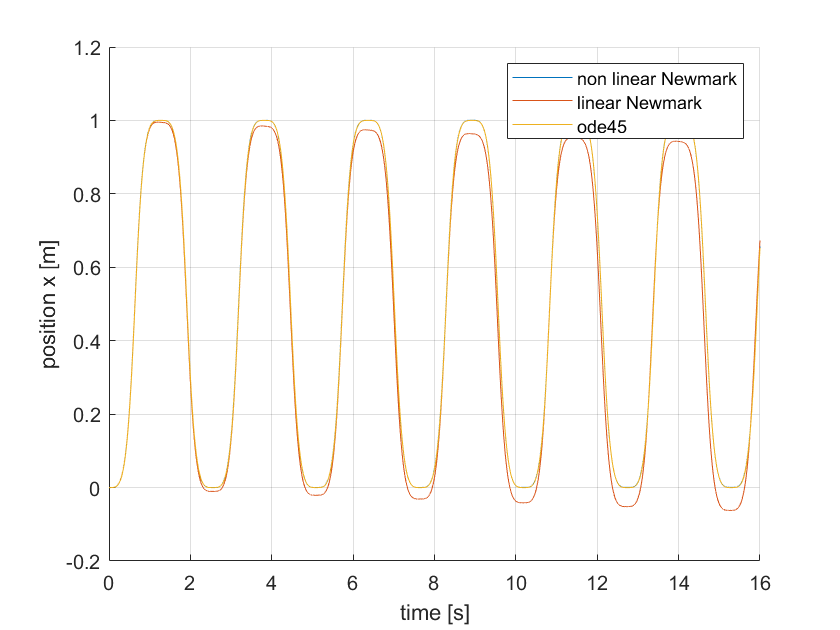


load('ode45_result.mat')
load('NewmarkLinear.mat')
hold on
plot(time, x_time_nonlin(1,:))
plot(time, x_time(1,:)) %linear case
plot(linspace(0,final_time,length(y)) , y(:,1), 'LineStyle', "--")
legend('non linear Newmark','linear Newmark', 'ode45')
xlabel('time [s]')
ylabel('position x [m]')
grid on
hold off